% COMPLETE SHAFT STRESS ANALYSIS 
% Kenneth Louis 81694903

% Formulas:
%   - Torsion (Shear):  Tau = (16 * T) / (pi * d^3)
%   - Bending (Normal): Sigma = (32 * M) / (pi * d^3)
%   - Transverse Shear: Tau_v = (4 * V) / (3 * Area)
%   - Von Mises:        VM = sqrt(Sigma^2 + 3 * Tau_total^2)
%   - Deflection:       Delta = (F * L^3) / (48 * E * I)
% =========================================================================


% reference page 378 


clear; clc; close all;




%% 1. INPUT PARAMETERS
% =========================================================================
% Geometry
d_mm = 60;                  % Shaft Diameter (mm)
d = d_mm / 1000;            % Convert to meters (0.06 m)
L = 0.9;                    % Arm Length (meters)




% Material Properties (4140 Steel - Pre-hardened)
Yield_Strength = 655e6;     % 655 MPa (Yield Point - Bending Limit)
Shear_Strength = 378e6;     % 378 MPa (Shear Yield Point)




% Keyway Stress Concentration Factors (Peterson's Stress Charts)


Kt_Bending = 2.14;          % Stress multiplier for Bending
Kt_Torsion = 3.00;          % Stress multiplier for Torsion




% Loads
Load_lbs = 250;             
Load_N = Load_lbs * 4.448;  % Scenario A: Normal Lift, this is conservative




Motor_Max_lb_in = 18290; % from NORD spec sheet
Motor_Max_Nm = Motor_Max_lb_in * 0.113; % Scenario B: Max Motor Torque (~2066 Nm)




%% 2. GEOMETRIC PROPERTIES CALCULATIONS
% =========================================================================
fprintf('Calculating Section Properties...\n');

Calculating Section Properties...






% Radius (c) - Distance from center to outer surface
c = d / 2;




% Cross-Sectional Area (for Transverse Shear)
Area = pi * c^2;




% Polar Moment of Inertia (J) - Resistance to Twisting
J = (pi * d^4) / 32;




% Area Moment of Inertia (I) - Resistance to Bending
I = (pi * d^4) / 64;




%% 3. SCENARIO A: NORMAL OPERATION (Lifting 250 lbs)
% =========================================================================
% Forces and Moments
Force_Lift = Load_N;            % Vertical Force
Torque_Lift = Force_Lift * L;   % Torque required to hold arm
Moment_Lift = Torque_Lift;      % Bending Moment (Worst case: Moment = Torque)




% --- A. TORSIONAL SHEAR CHECK ---
% Nominal Stress (Smooth shaft)
Tau_Torsion_Nom_Lift = (Torque_Lift * c) / J;
% Peak Stress (Inside Keyway)
Tau_Torsion_Peak_Lift = Tau_Torsion_Nom_Lift * Kt_Torsion;




% --- B. BENDING STRESS CHECK ---
% Nominal Stress
Sigma_Bend_Nom_Lift = (Moment_Lift * c) / I;
% Peak Stress (Inside Keyway)
Sigma_Bend_Peak_Lift = Sigma_Bend_Nom_Lift * Kt_Bending;




% --- C. TRANSVERSE SHEAR CHECK ---
% The force trying to slice the shaft 
Tau_Transverse_Lift = (4 * Force_Lift) / (3 * Area);




% --- D. COMBINED VON MISES STRESS ---
% Total Shear = Torsion + Transverse
Tau_Total_Lift = Tau_Torsion_Peak_Lift + Tau_Transverse_Lift;




% Von Mises Formula: sqrt(Sigma^2 + 3*Tau^2)
VM_Lift = sqrt(Sigma_Bend_Peak_Lift^2 + 3 * Tau_Total_Lift^2);




% Safety Factor
SF_Lift = Yield_Strength / VM_Lift;




%% 4. SCENARIO B: STALL CONDITION (Full Motor Torque)
% =========================================================================
% Forces and Moments (Assuming table hits a wall or held by brake) 
% not rotating
Torque_Stall = Motor_Max_Nm;    % Full 18,290 lb-in
Moment_Stall = Motor_Max_Nm;    % Bending Moment matches Torque
Force_Stall = Torque_Stall / L; % Reaction force at tip




% --- A. TORSIONAL SHEAR CHECK ---
Tau_Torsion_Nom_Stall = (Torque_Stall * c) / J;
Tau_Torsion_Peak_Stall = Tau_Torsion_Nom_Stall * Kt_Torsion; % Apply Kt




% --- B. BENDING STRESS CHECK ---
Sigma_Bend_Nom_Stall = (Moment_Stall * c) / I;
Sigma_Bend_Peak_Stall = Sigma_Bend_Nom_Stall * Kt_Bending;   % Apply Kt




% --- C. TRANSVERSE SHEAR CHECK ---
Tau_Transverse_Stall = (4 * Force_Stall) / (3 * Area);




% --- D. COMBINED VON MISES STRESS ---
Tau_Total_Stall = Tau_Torsion_Peak_Stall + Tau_Transverse_Stall;
VM_Stall = sqrt(Sigma_Bend_Peak_Stall^2 + 3 * Tau_Total_Stall^2);




% Safety Factor
SF_Stall = Yield_Strength / VM_Stall;




%% 5. DETAILED OUTPUT REPORT
% =========================================================================
fprintf('\n==========================================================\n');

fprintf('        DETAILED SHAFT STRESS REPORT (with Keyway Kt)     \n');

        DETAILED SHAFT STRESS REPORT (with Keyway Kt)     


fprintf('==========================================================\n');

fprintf('Shaft Diameter: %.0f mm\n', d_mm);

Shaft Diameter: 60 mm


fprintf('Material Yield: %.0f MPa\n', Yield_Strength/1e6);

Material Yield: 655 MPa


fprintf('Keyway Factors: Kt_Bend=%.2f, Kt_Twist=%.2f\n', Kt_Bending, Kt_Torsion);

Keyway Factors: Kt_Bend=2.14, Kt_Twist=3.00


fprintf('----------------------------------------------------------\n');

----------------------------------------------------------






% Report Scenario A
fprintf('\nSCENARIO A: NORMAL LIFTING (Load: %.0f lbs)\n', Load_lbs);


SCENARIO A: NORMAL LIFTING (Load: 250 lbs)


fprintf('  1. Bending Stress:     %6.2f MPa (Peak)\n', Sigma_Bend_Peak_Lift/1e6);

  1. Bending Stress:     101.00 MPa (Peak)


fprintf('  2. Torsional Stress:   %6.2f MPa (Peak)\n', Tau_Torsion_Peak_Lift/1e6);

  2. Torsional Stress:    70.79 MPa (Peak)


fprintf('  3. Transverse Shear:   %6.2f MPa (Negligible)\n', Tau_Transverse_Lift/1e6);

  3. Transverse Shear:     0.52 MPa (Negligible)


fprintf('  --------------------------------\n');

  --------------------------------


fprintf('  TOTAL VON MISES:       %6.2f MPa\n', VM_Lift/1e6);

  TOTAL VON MISES:       159.56 MPa


fprintf('  SAFETY FACTOR:         %6.2f  (Safe)\n', SF_Lift);

  SAFETY FACTOR:           4.11  (Safe)






% Report Scenario B
fprintf('\nSCENARIO B: CRASH / MOTOR STALL (%.0f Nm)\n', Motor_Max_Nm);


SCENARIO B: CRASH / MOTOR STALL (2067 Nm)


fprintf('  1. Bending Stress:     %6.2f MPa (Peak)\n', Sigma_Bend_Peak_Stall/1e6);

  1. Bending Stress:     208.57 MPa (Peak)


fprintf('  2. Torsional Stress:   %6.2f MPa (Peak)\n', Tau_Torsion_Peak_Stall/1e6);

  2. Torsional Stress:   146.19 MPa (Peak)


fprintf('  3. Transverse Shear:   %6.2f MPa\n', Tau_Transverse_Stall/1e6);

  3. Transverse Shear:     1.08 MPa


fprintf('  --------------------------------\n');

  --------------------------------


fprintf('  TOTAL VON MISES:       %6.2f MPa\n', VM_Stall/1e6);

  TOTAL VON MISES:       329.50 MPa


fprintf('  SAFETY FACTOR:         %6.2f\n', SF_Stall);

  SAFETY FACTOR:           1.99






if SF_Stall > 1.0
    fprintf('\n  >>> CONCLUSION: PASS. Shaft survives stall torque (barely).\n');
else
    fprintf('\n  >>> CONCLUSION: FAIL. Keyway will crack under stall load.\n');
end


  >>> CONCLUSION: PASS. Shaft survives stall torque (barely).


fprintf('==========================================================\n');

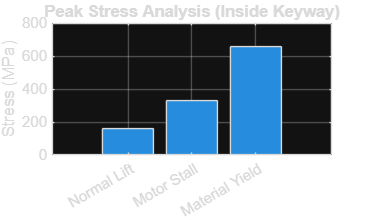





%% 6. PLOT (Original Single Material)
figure('Color','white');
bar([VM_Lift/1e6, VM_Stall/1e6, Yield_Strength/1e6], 'FaceColor', 'flat');
ylabel('Stress (MPa)');
xticklabels({'Normal Lift', 'Motor Stall', 'Material Yield'});
title('Peak Stress Analysis (Inside Keyway)');
grid on;





%% 7. MULTI-MATERIAL STRENGTH COMPARISON (EXTENDED LIST)
% =========================================================================
% Using different materials


Material_Names = {'1045 Steel', '4140 Pre-Hard', 'Titanium Gr5', '4340 Heat Treated', '17-4 PH Stainless'};
Yield_Values = [530e6, 655e6, 880e6, 1030e6, 1170e6];


% Initialize Safety Factor Array
Safety_Factors = zeros(1, length(Yield_Values));


fprintf('\n==========================================================\n');

fprintf('   FULL MATERIAL COMPARISON (MOTOR STALL SCENARIO)        \n');

   FULL MATERIAL COMPARISON (MOTOR STALL SCENARIO)        


fprintf('==========================================================\n');

fprintf('Applied Von Mises Stress: %.2f MPa\n', VM_Stall/1e6);

Applied Von Mises Stress: 329.50 MPa


fprintf('----------------------------------------------------------\n');

----------------------------------------------------------




for i = 1:length(Yield_Values)
    Safety_Factors(i) = Yield_Values(i) / VM_Stall;
    
    if Safety_Factors(i) >= 1.0, Status = 'PASS'; else, Status = 'FAIL'; end
    fprintf('%d. %-20s (Yield: %4.0f MPa) -> SF: %.2f [%s]\n', ...
        i, Material_Names{i}, Yield_Values(i)/1e6, Safety_Factors(i), Status);
end

1. 1045 Steel           (Yield:  530 MPa) -> SF: 1.61 [PASS]
2. 4140 Pre-Hard        (Yield:  655 MPa) -> SF: 1.99 [PASS]
3. Titanium Gr5         (Yield:  880 MPa) -> SF: 2.67 [PASS]
4. 4340 Heat Treated    (Yield: 1030 MPa) -> SF: 3.13 [PASS]
5. 17-4 PH Stainless    (Yield: 1170 MPa) -> SF: 3.55 [PASS]


fprintf('==========================================================\n');

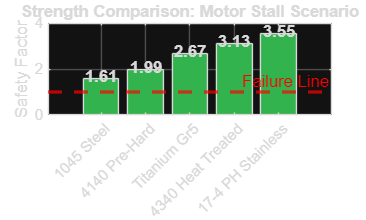





%% 8. SIDE-BY-SIDE PLOT COMPARISON (STRENGTH)
% =========================================================================
figure('Color','white', 'Name', 'Strength Comparison');


% Create Bar Chart
b = bar(Safety_Factors);
b.FaceColor = 'flat';
for k = 1:length(Safety_Factors)
    if Safety_Factors(k) < 1.0
        b.CData(k,:) = [0.8 0.2 0.2]; % Red
    elseif Safety_Factors(k) < 1.5
        b.CData(k,:) = [0.9 0.7 0.1]; % Orange
    else
        b.CData(k,:) = [0.2 0.7 0.3]; % Green
    end
end
hold on;
yline(1.0, 'r--', 'Failure Line', 'LineWidth', 2);
ylabel('Safety Factor');
title('Strength Comparison: Motor Stall Scenario');
set(gca, 'XTickLabel', Material_Names, 'XTickLabelRotation', 45);
grid on;
for i = 1:length(Safety_Factors)
    text(i, Safety_Factors(i) + 0.1, sprintf('%.2f', Safety_Factors(i)), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end





%% 9. STIFFNESS & DEFLECTION COMPARISON (ALL MATERIALS)
% =========================================================================
%not accurate , need ot double check


Shaft_Len = 3.1; % meters


% Elastic Modulus (E) and Shear Modulus (G) in Pascals
% 1. 1045 Steel (Standard)
% 2. 4140 Pre-Hard (Standard Steel)
% 3. Titanium Gr5 (Flexible)
% 4. 4340 Heat Treated (Standard Steel)
% 5. 17-4 PH Stainless (Slightly more flexible than carbon steel)


E_Values = [205e9, 205e9, 114e9, 205e9, 196e9]; % Young's Modulus
G_Values = [80e9,  80e9,  44e9,  80e9,  77e9];  % Shear Modulus
Densities = [7850, 7850, 4430, 7850, 7750];     % Density kg/m^3


Twist_Results = zeros(1, length(Material_Names));
Sag_Results = zeros(1, length(Material_Names));


fprintf('\n==========================================================\n');

fprintf('   STIFFNESS & SAG COMPARISON (SHAFT LEN = %.1f m)        \n', Shaft_Len);

   STIFFNESS & SAG COMPARISON (SHAFT LEN = 3.1 m)        


fprintf('==========================================================\n');

fprintf('%-20s | %-12s | %-12s\n', 'Material', 'Twist (Deg)', 'Sag (mm)');

Material             | Twist (Deg)  | Sag (mm)    


fprintf('----------------------------------------------------------\n');

----------------------------------------------------------




for i = 1:length(Material_Names)
    % 1. Twist (Torsional Deflection)
    % Formula: Theta (rad) = (Torque * L) / (J * G)
    Theta_Rad = (Torque_Stall * Shaft_Len) / (J * G_Values(i));
    Twist_Results(i) = Theta_Rad * (180/pi);
    
    % 2. Sag (Bending Deflection due to Load + Self-Weight)
    Shaft_Weight_N = (Area * Shaft_Len * Densities(i)) * 9.81;
    Total_Load = Load_N + (Shaft_Weight_N/2);
    
    % Formula: Delta = (F * L^3) / (48 * E * I)
    Deflection_m = (Total_Load * Shaft_Len^3) / (48 * E_Values(i) * I);
    Sag_Results(i) = Deflection_m * 1000;
    
    fprintf('%-20s | %6.2f deg    | %6.2f mm\n', ...
        Material_Names{i}, Twist_Results(i), Sag_Results(i));
end

1045 Steel           |   3.61 deg    |   6.90 mm
4140 Pre-Hard        |   3.61 deg    |   6.90 mm
Titanium Gr5         |   6.56 deg    |  11.15 mm
4340 Heat Treated    |   3.61 deg    |   6.90 mm
17-4 PH Stainless    |   3.75 deg    |   7.19 mm


fprintf('==========================================================\n');

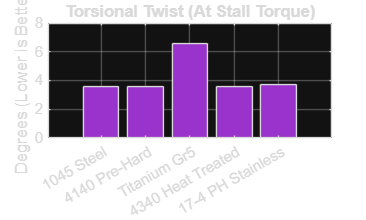



% --- PLOT STIFFNESS ---
figure('Color','white', 'Name', 'Stiffness Comparison');
%subplot(2,1,1);
bar(Twist_Results, 'FaceColor', [0.6 0.2 0.8]);
title('Torsional Twist (At Stall Torque)');
ylabel('Degrees (Lower is Better)');
set(gca, 'XTickLabel', Material_Names);
grid on;

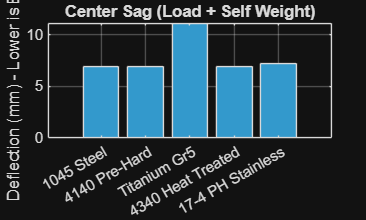





figure
%subplot(2,1,2);
bar(Sag_Results, 'FaceColor', [0.2 0.6 0.8]);
title('Center Sag (Load + Self Weight)');
ylabel('Deflection (mm) - Lower is Better');
set(gca, 'XTickLabel', Material_Names);
grid on;



%% 10. [NEW] SHAFT KEY CALCULATIONS
% =========================================================================
% Standard rectangular key for a 60mm shaft (DIN 6885 / ISO R773)
% Key Dimensions: 18mm (Width) x 11mm (Height)
% Length: Assumed 70mm 
% Material: C1018 Steel (Softer than shaft, acts as a fuse)

Key_Width   = 18 / 1000;  % 18mm (Standard for 60mm shaft)
Key_Height  = 11 / 1000;  % 11mm (Standard for 60mm shaft)
Key_Length  = 80/1000 %d*1.5;  % 90mm

Key_Length = 0.0800

Key_Yield   = 300e6;      %https://www.google.com/search?q=yield+strength+1008-1045+Carbon+Steel&client=firefox-b-d&hs=Kns9&sca_esv=393d4397518a9c36&sxsrf=ANbL-n7L2Yr_tZ9g8XwupPp2NGLiidbCCw%3A1769153902065&ei=biVzaZvaA9i-0PEP2-ml4QY&ved=0ahUKEwibyYrvk6GSAxVYHzQIHdt0KWwQ4dUDCBE&uact=5&oq=yield+strength+1008-1045+Carbon+Steel&gs_lp=Egxnd3Mtd2l6LXNlcnAiJXlpZWxkIHN0cmVuZ3RoIDEwMDgtMTA0NSBDYXJib24gU3RlZWwyBBAjGCcyBRAAGO8FMgUQABjvBTIFEAAY7wUyCBAAGIAEGKIESLnBA1DhvwNY4b8DcAJ4AZABAJgBTaABTaoBATG4AQPIAQD4AQGYAgOgAljCAgoQABhHGNYEGLADmAMAiAYBkAYIkgcBM6AHywSyBwExuAdQwgcDMC4zyAcFgAgB&sclient=gws-wiz-serp
%  370 MPa (Typical Low Carbon Steel)
Key_Shear_Yield = Key_Yield * 0.577; % Von Mises estimate for Shear Yield

% Force acting on the Key (Force = Torque / Radius)
Force_on_Key = Torque_Stall / c;

% A. CHECK SHEAR (Slicing the key in half)
Area_Shear = Key_Width * Key_Length;
Stress_Shear = Force_on_Key / Area_Shear;
SF_Key_Shear = Key_Shear_Yield / Stress_Shear;

% B. CHECK CRUSHING (Bearing pressure on side of key)
% Only half the key height is in contact
Area_Crush = (Key_Height / 2) * Key_Length;
Stress_Crush = Force_on_Key / Area_Crush;
SF_Key_Crush = Key_Yield / Stress_Crush;

fprintf('\n==========================================================\n');

fprintf('   SHAFT KEY ANALYSIS (18mm x 11mm x 70mm)\n');

   SHAFT KEY ANALYSIS (18mm x 11mm x 70mm)


fprintf('==========================================================\n');

fprintf('Force on Key:          %.0f N  (%.0f lbs)\n', Force_on_Key, Force_on_Key/4.448);

Force on Key:          68892 N  (15488 lbs)


fprintf('----------------------------------------------------------\n');

----------------------------------------------------------


fprintf('1. Shear Stress:       %6.2f MPa (Limit: %.0f)\n', Stress_Shear/1e6, Key_Shear_Yield/1e6);

1. Shear Stress:        47.84 MPa (Limit: 173)


fprintf('   Safety Factor:      %.2f\n', SF_Key_Shear);

   Safety Factor:      3.62


fprintf('2. Crushing Stress:    %6.2f MPa (Limit: %.0f)\n', Stress_Crush/1e6, Key_Yield/1e6);

2. Crushing Stress:    156.57 MPa (Limit: 300)


fprintf('   Safety Factor:      %.2f\n', SF_Key_Crush);

   Safety Factor:      1.92



if SF_Key_Shear < 1.0 || SF_Key_Crush < 1.0
    fprintf('\n  >>> RESULT: FAIL. Key will shear or deform.\n');
else
    fprintf('\n  >>> RESULT: PASS. Key is strong enough.\n');
end


  >>> RESULT: PASS. Key is strong enough.




%% 11. [NEW] GROOVE ANALYSIS (Stress Concentration for Retaining Ring)
% =========================================================================
% Retaining Rings (Circlips) require a groove.
% Grooves are dangerous because they have sharp corners (High Kt).

% Typical Snap Ring Groove for 60mm Shaft:
% Depth: ~2.0 mm | Corner Radius: ~0.2 mm (Very Sharp!)

Kt_Groove_Bending = 4.0; % Approx Kt for sharp groove (higher than keyway!)
d_groove = d - (2 * 0.002); % Diameter at bottom of groove (56mm)

% Calculate Bending Stress inside the Groove
I_groove = (pi * d_groove^4) / 64;
Sigma_Groove = ((Moment_Stall * (d_groove/2)) / I_groove) * Kt_Groove_Bending;

SF_Groove = Yield_Strength / Sigma_Groove;

fprintf('\n==========================================================\n');

fprintf('   GROOVE ANALYSIS (If using Retaining Ring/Circlip)\n');

   GROOVE ANALYSIS (If using Retaining Ring/Circlip)


fprintf('==========================================================\n');

fprintf('Note: Clamp Collars do NOT need this groove. Avoid if possible.\n');

Note: Clamp Collars do NOT need this groove. Avoid if possible.


fprintf('Groove Kt Factor:      %.2f (Sharp Notch)\n', Kt_Groove_Bending);

Groove Kt Factor:      4.00 (Sharp Notch)


fprintf('Stress in Groove:      %6.2f MPa\n', Sigma_Groove/1e6);

Stress in Groove:      479.50 MPa


fprintf('Safety Factor:         %.2f\n', SF_Groove);

Safety Factor:         1.37



if SF_Groove < 1.0
    fprintf('\n  >>> WARNING: Groove causes SHAFT FAILURE under stall load.\n');
    fprintf('      Use a Clamp-On Collar instead of a Snap Ring.\n');
else
    fprintf('\n  >>> RESULT: Pass, but stress is very high.\n');
end


  >>> RESULT: Pass, but stress is very high.


fprintf('==========================================================\n');